clear;
clc;
FS = 48000;
fc = 15000; %% modulating frequency
Ac = 4;

# **CA1-Q3-810101429**

#### ***Reading the input:***

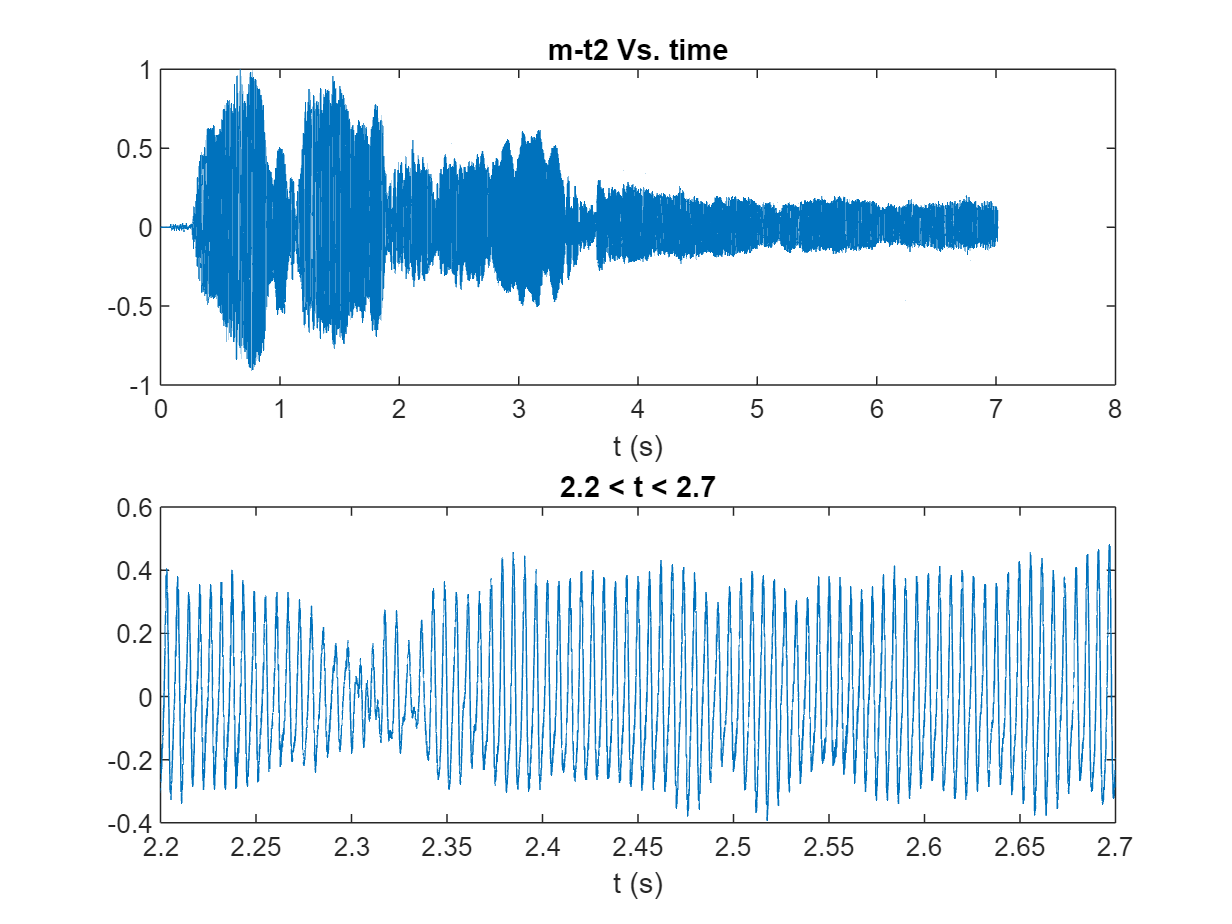

x_in = audioread('m_t2.mp3');
x_in = x_in/max(abs(x_in));

% sound(x_in, FS);

time_domain = (0:length(x_in)-1) / FS;
time_domain2 = time_domain';
figure;
subplot(2,1,1);
plot(time_domain, x_in);
xlabel('t (s)');
title('m-t2 Vs. time');
subplot(2,1,2);
plot(time_domain, x_in);
xlabel('t (s)');
title('2.2 < t < 2.7');
xlim([2.2, 2.7]);

***Calculating the Fourier Transform of the input signal:***

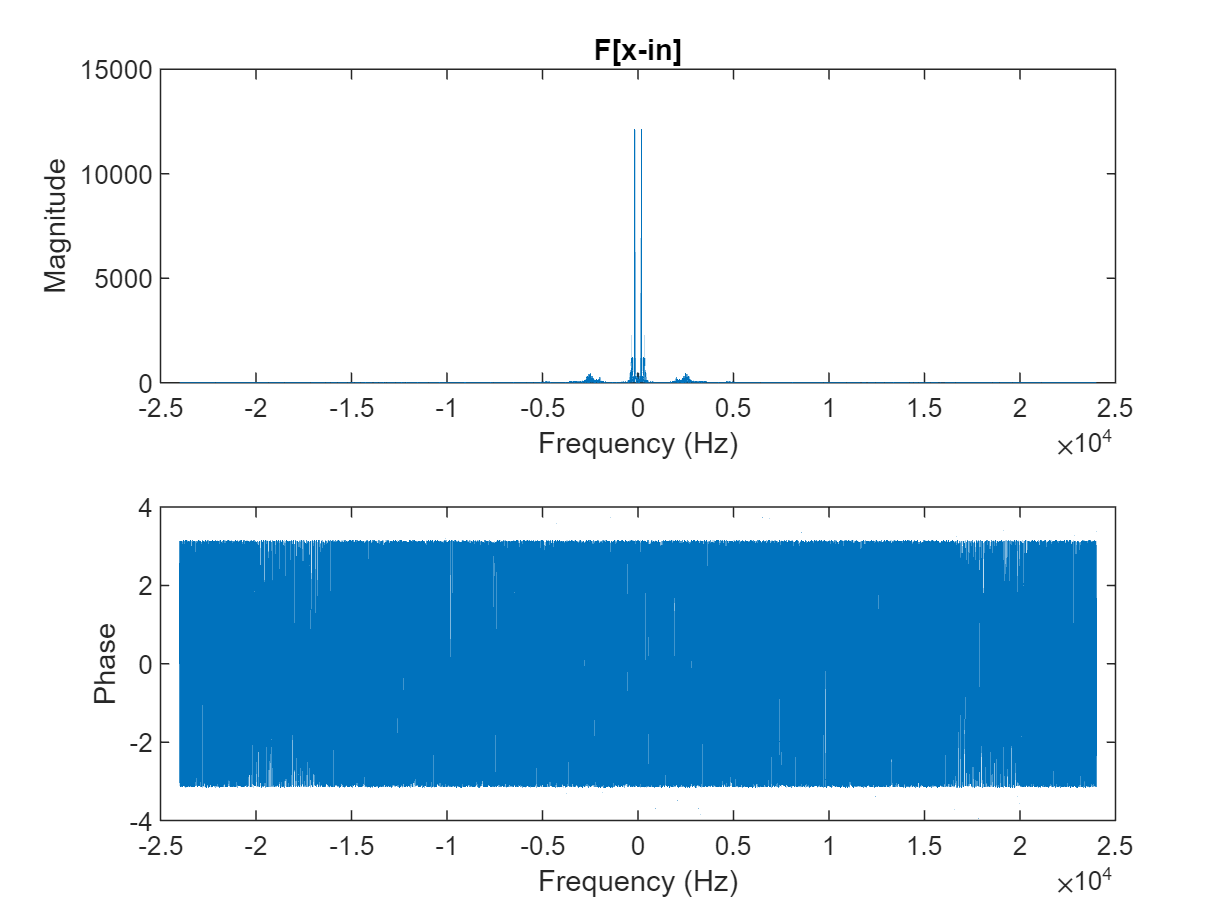

F_x = fftshift(fft(x_in));
n_x = length(x_in);
f_x = (-n_x/2:n_x/2-1)*(FS/n_x);


figure;
subplot(2,1,1);
plot(f_x,abs(F_x));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[x-in]');
subplot(2,1,2);
plot(f_x,angle(F_x));
xlabel('Frequency (Hz)');
ylabel('Phase');

***Filtering the input signal:***

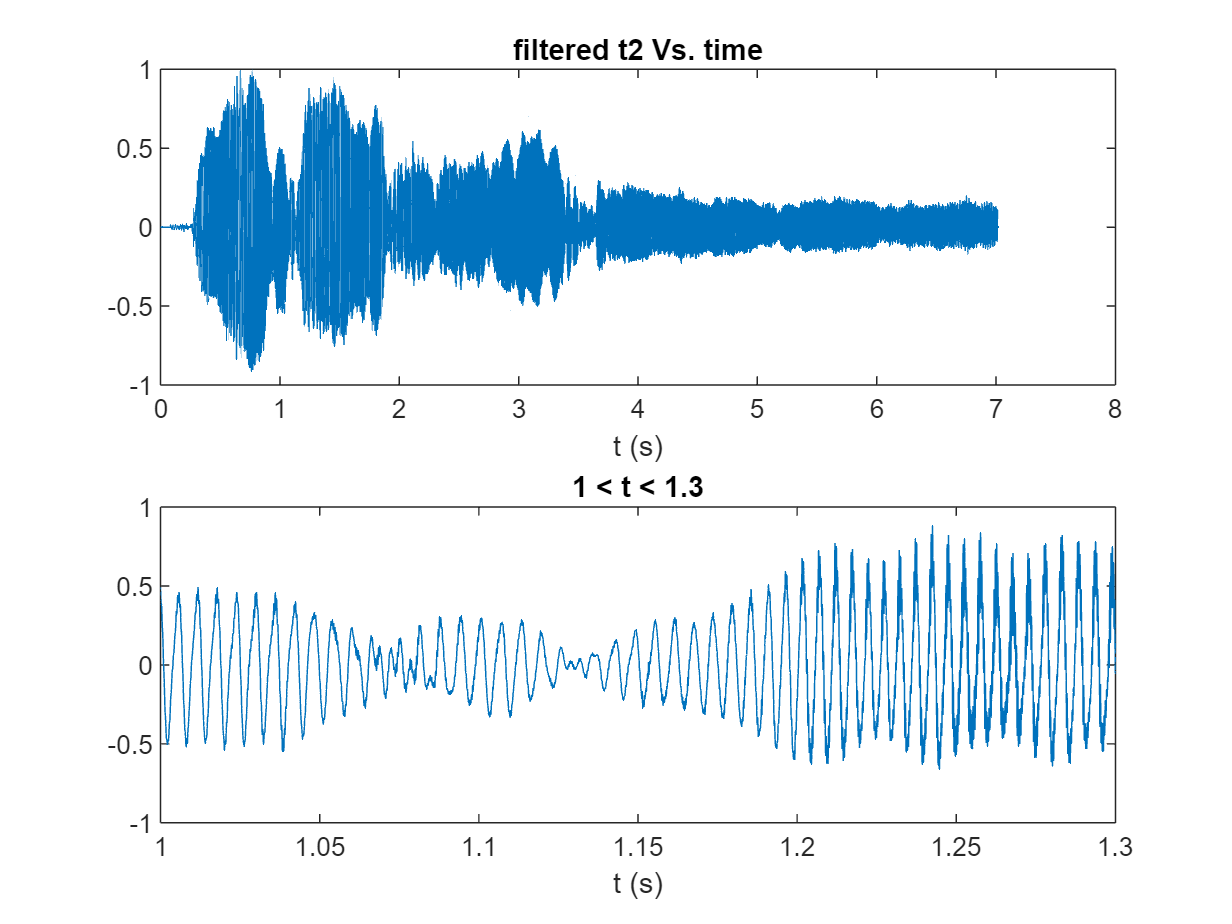

Fx_filtered_5k = LPfilter(F_x, f_x, 5000);
x_in_filtered_5k = ifft(ifftshift(Fx_filtered_5k));

% sound(x_in_filtered_5k, FS);

figure;
subplot(2,1,1);
plot(time_domain, x_in_filtered_5k);
xlabel('t (s)');
title('filtered t2 Vs. time');
subplot(2,1,2);
plot(time_domain, x_in_filtered_5k);
xlabel('t (s)');
title('1 < t < 1.3');
xlim([1, 1.3]);

***Calculating the Hilbert transform of the input signal:***

Fx_tilda = Hilbert(Fx_filtered_5k, f_x);
x_tilda = ifft(ifftshift(Fx_tilda));

***SSB modulation:***

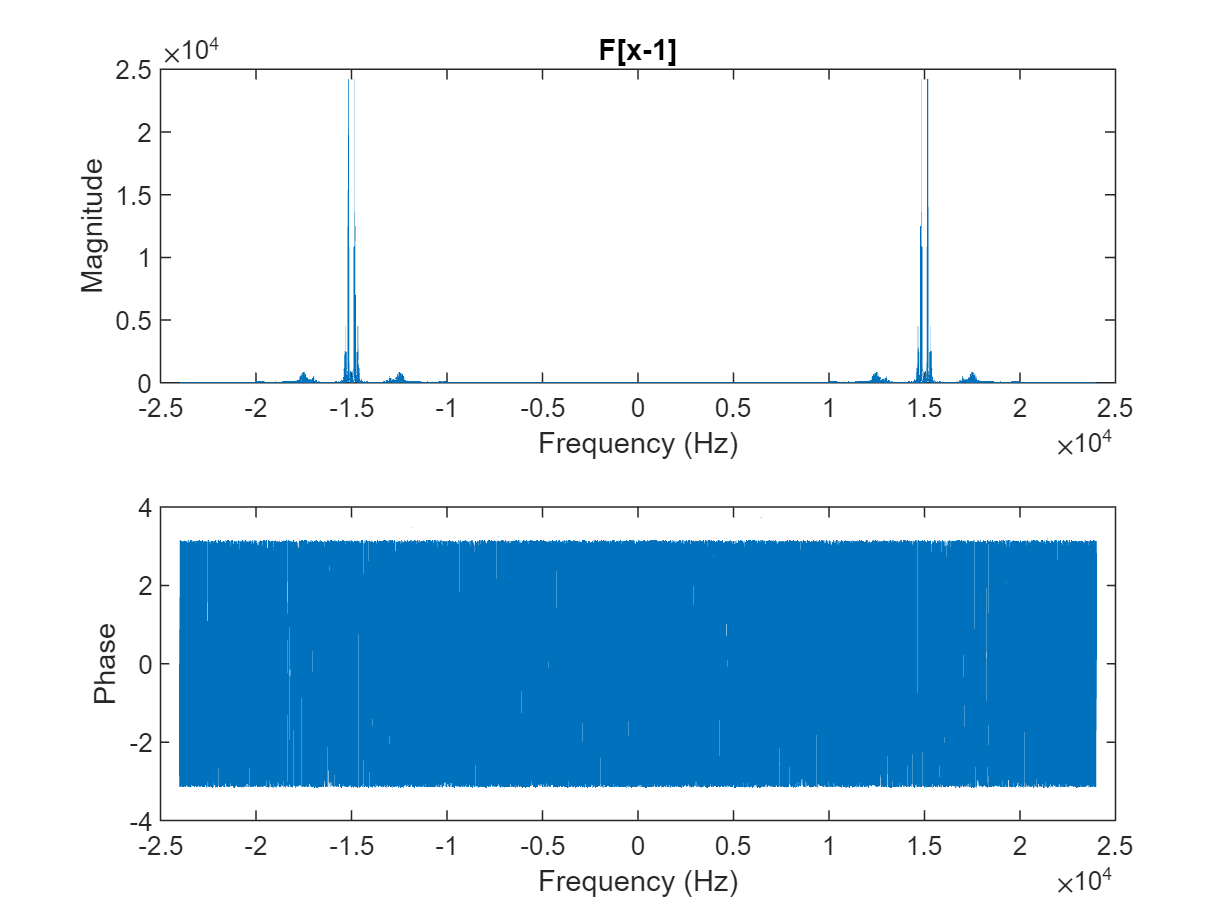

x_1 = Ac * cos(2*pi*fc*time_domain2) .* x_in_filtered_5k;
x_2 = Ac * sin(2*pi*fc*time_domain2) .* x_tilda;

F_x_1 = fftshift(fft(x_1));
F_x_2 = fftshift(fft(x_2));

figure;
subplot(2,1,1);
plot(f_x,abs(F_x_1));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[x-1]');
subplot(2,1,2);
plot(f_x,angle(F_x_1));
xlabel('Frequency (Hz)');
ylabel('Phase');

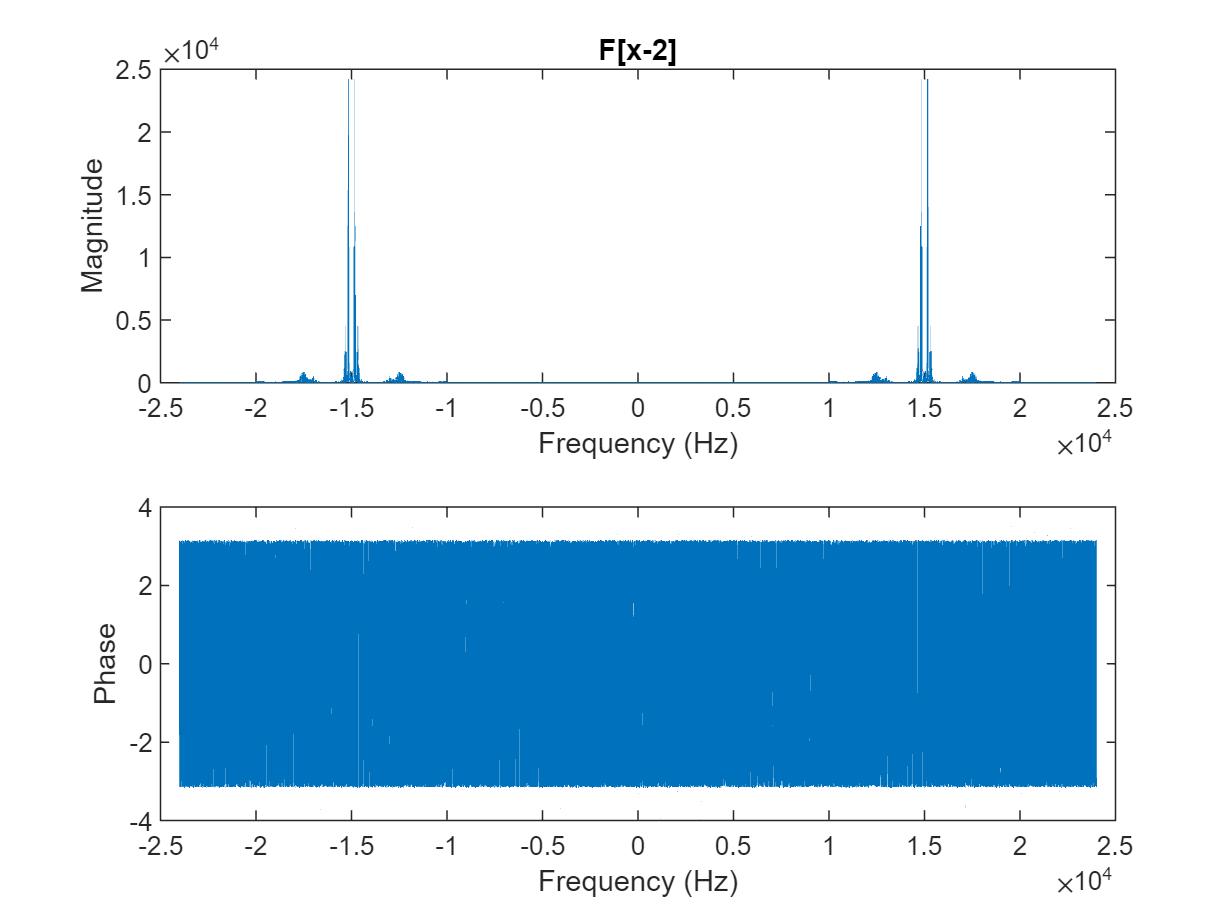


figure;
subplot(2,1,1);
plot(f_x,abs(F_x_2));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[x-2]');
subplot(2,1,2);
plot(f_x,angle(F_x_2));
xlabel('Frequency (Hz)');
ylabel('Phase');

***USB modulation:***

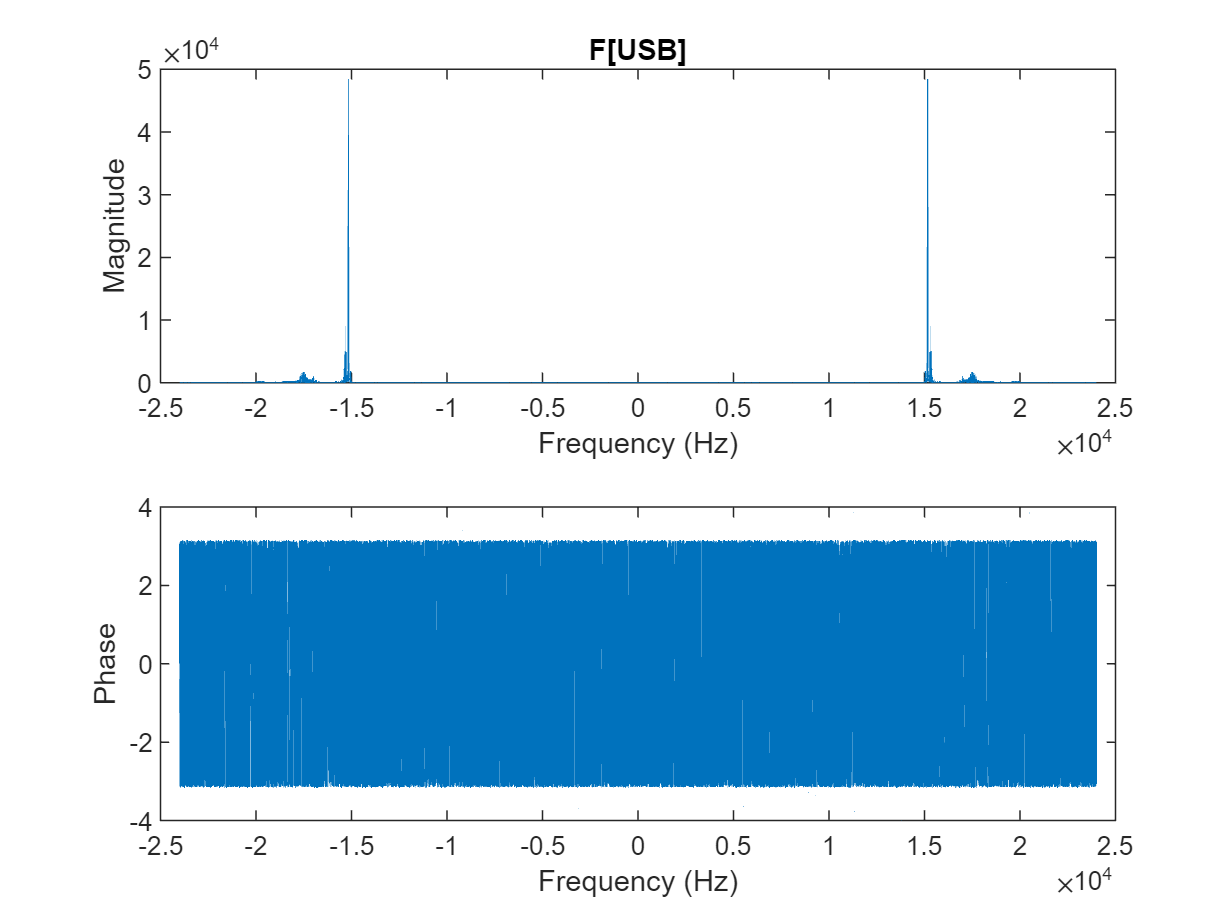

USB_out = x_1 - x_2;
F_USB_out = fftshift(fft(USB_out));

figure;
subplot(2,1,1);
plot(f_x,abs(F_USB_out));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[USB]');
subplot(2,1,2);
plot(f_x,angle(F_USB_out));
xlabel('Frequency (Hz)');
ylabel('Phase');

***LSB modulation:***

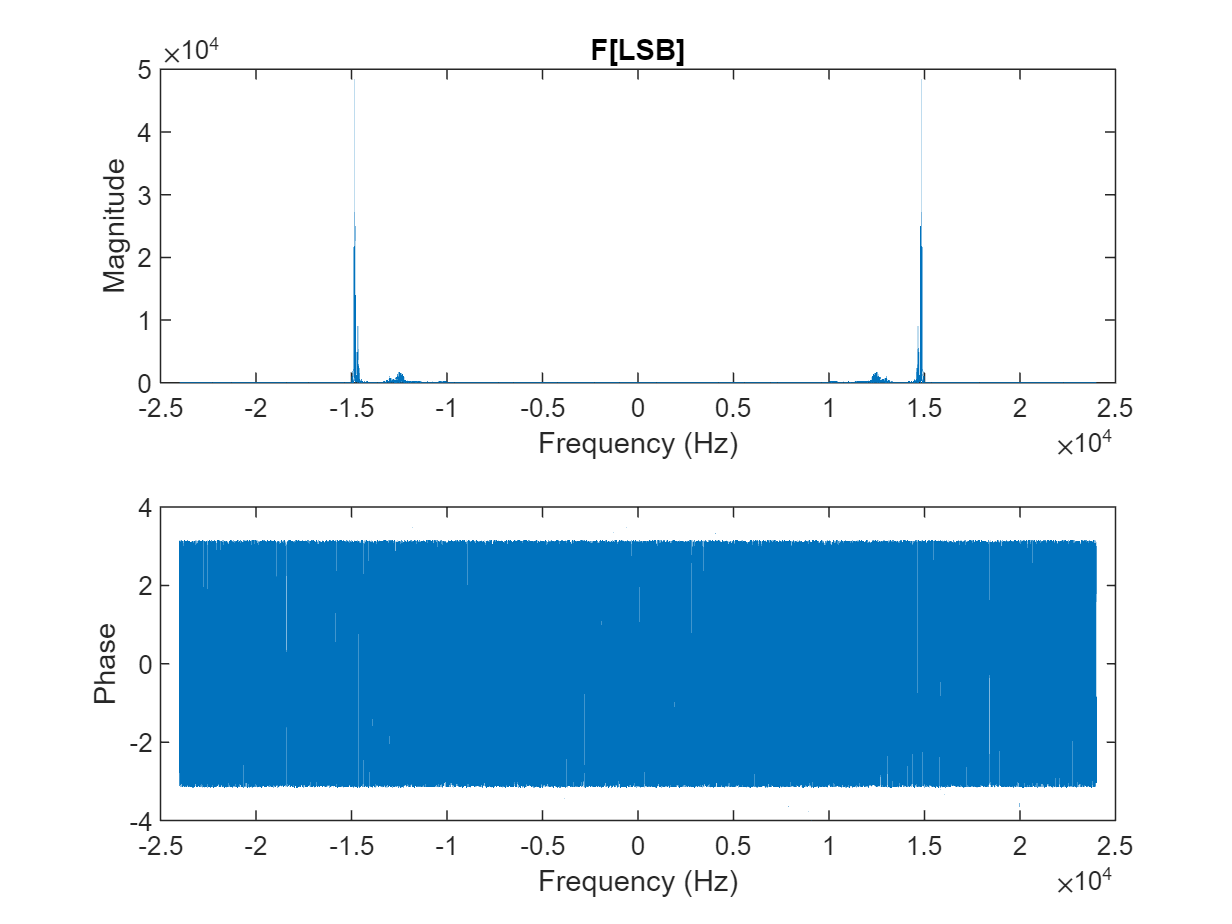

LSB_out = x_1 + x_2;
F_LSB_out = fftshift(fft(LSB_out));

figure;
subplot(2,1,1);
plot(f_x,abs(F_LSB_out));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[LSB]');
subplot(2,1,2);
plot(f_x,angle(F_LSB_out));
xlabel('Frequency (Hz)');
ylabel('Phase');

***Demodulation:***

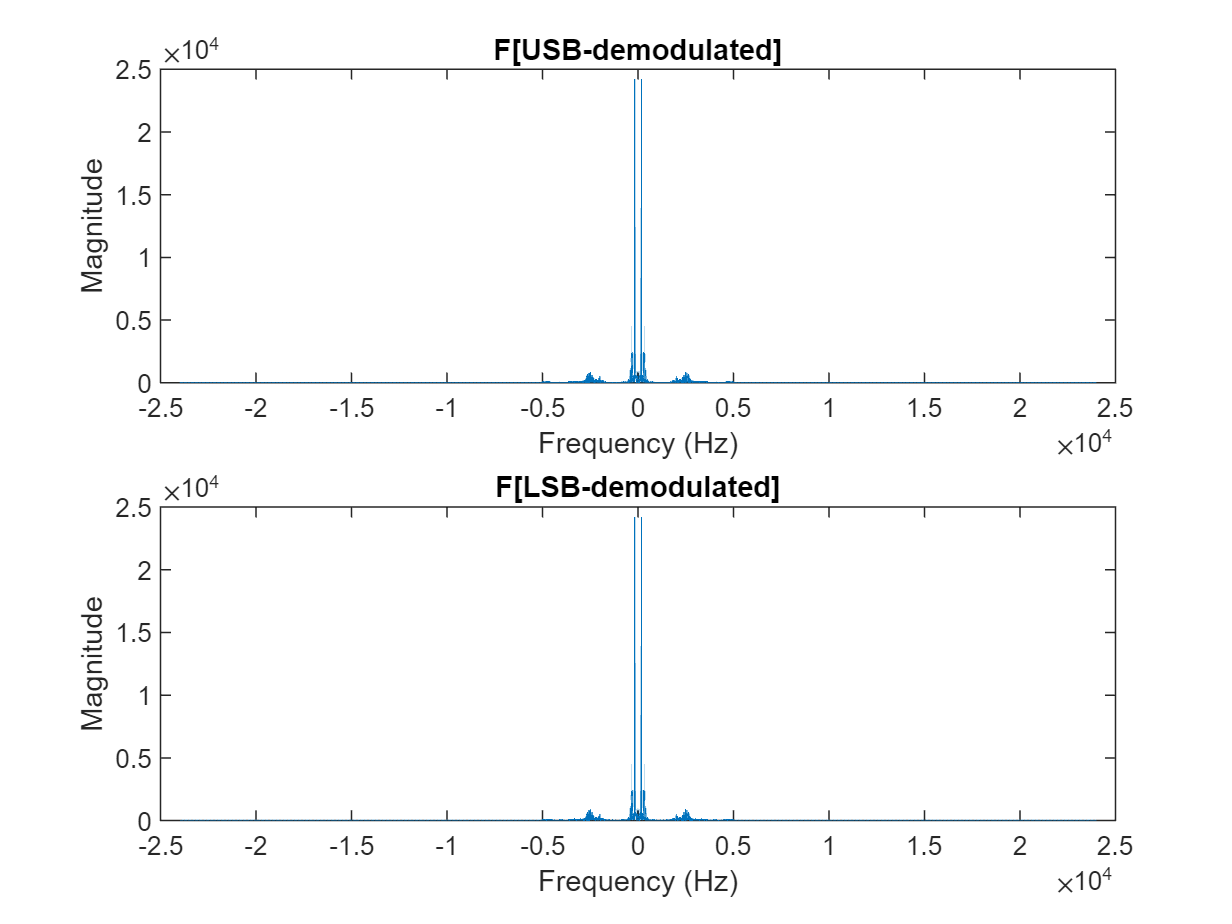

x_dm_USB = cos(2*pi*fc*time_domain2) .* USB_out;
F_x_dm_USB = fftshift(fft(x_dm_USB));
F_USB_out = LPfilter(F_x_dm_USB, f_x, 5000);
x_USB_out = ifft(ifftshift(F_USB_out));

% sound(real(x_USB_out), FS);

x_dm_LSB = cos(2*pi*fc*time_domain2) .* LSB_out;
F_x_dm_LSB = fftshift(fft(x_dm_LSB));
F_LSB_out = LPfilter(F_x_dm_LSB, f_x, 5000);
x_LSB_out = ifft(ifftshift(F_LSB_out));

% sound(real(x_LSB_out), FS);


figure;
subplot(2,1,1);
plot(f_x,abs(F_USB_out));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[USB-demodulated]');
subplot(2,1,2);
plot(f_x,abs(F_LSB_out));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[LSB-demodulated]');

***Plotting for USB:***

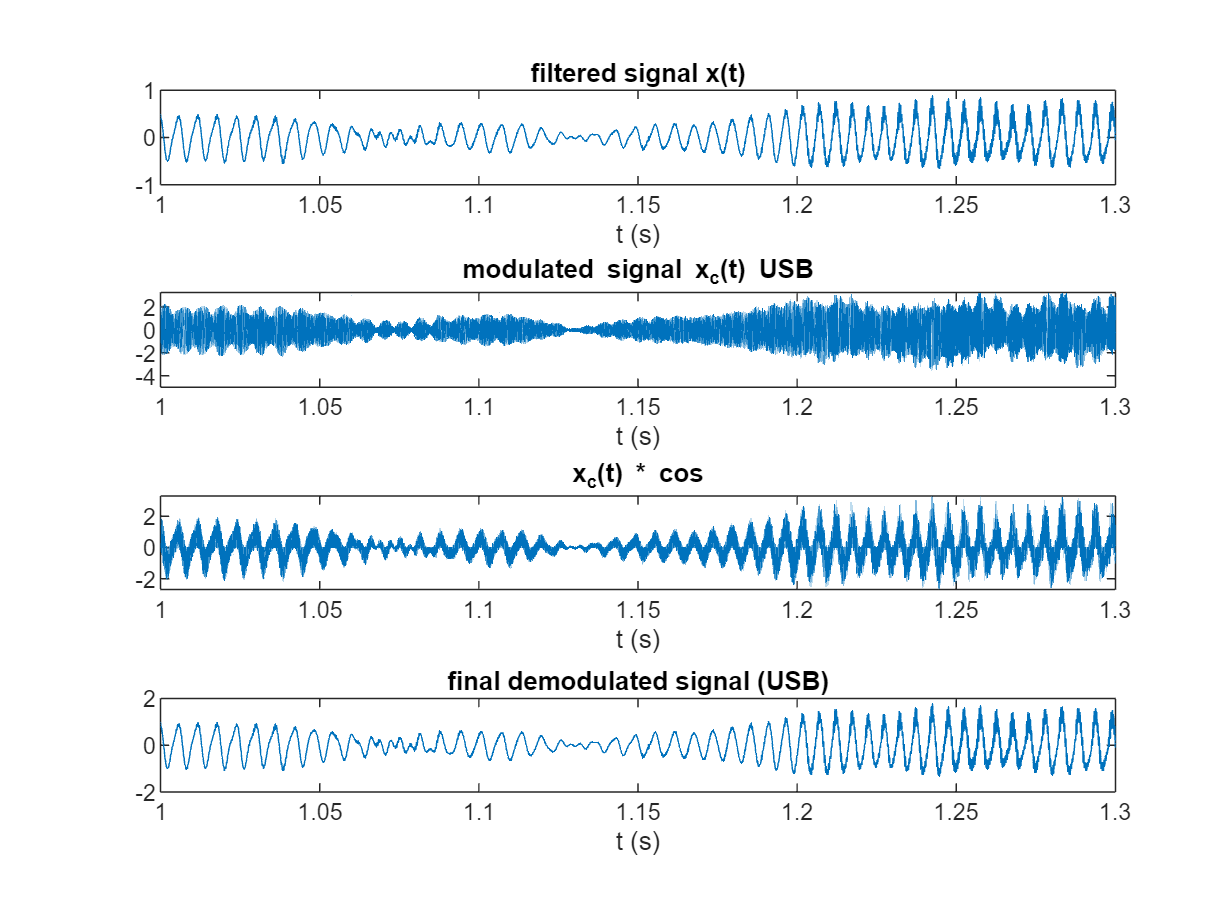

figure;
subplot(4,1,1);
plot (time_domain, x_in_filtered_5k);
xlabel('t (s)');
title('filtered signal x(t)');
xlim([1,1.3]);
subplot(4,1,2);
plot(time_domain, real(USB_out));
xlabel('t (s)');
title('modulated signal x_c(t) USB');
xlim([1,1.3]);
subplot(4,1,3);
plot(time_domain , real(x_dm_USB));
xlabel('t (s)');
title('x_c(t) * cos');
xlim([1,1.3]);
subplot(4,1,4);
plot(time_domain, real(x_USB_out));
xlabel('t (s)');
title('final demodulated signal (USB)');
xlim([1,1.3]);

***Plotting for LSB:***

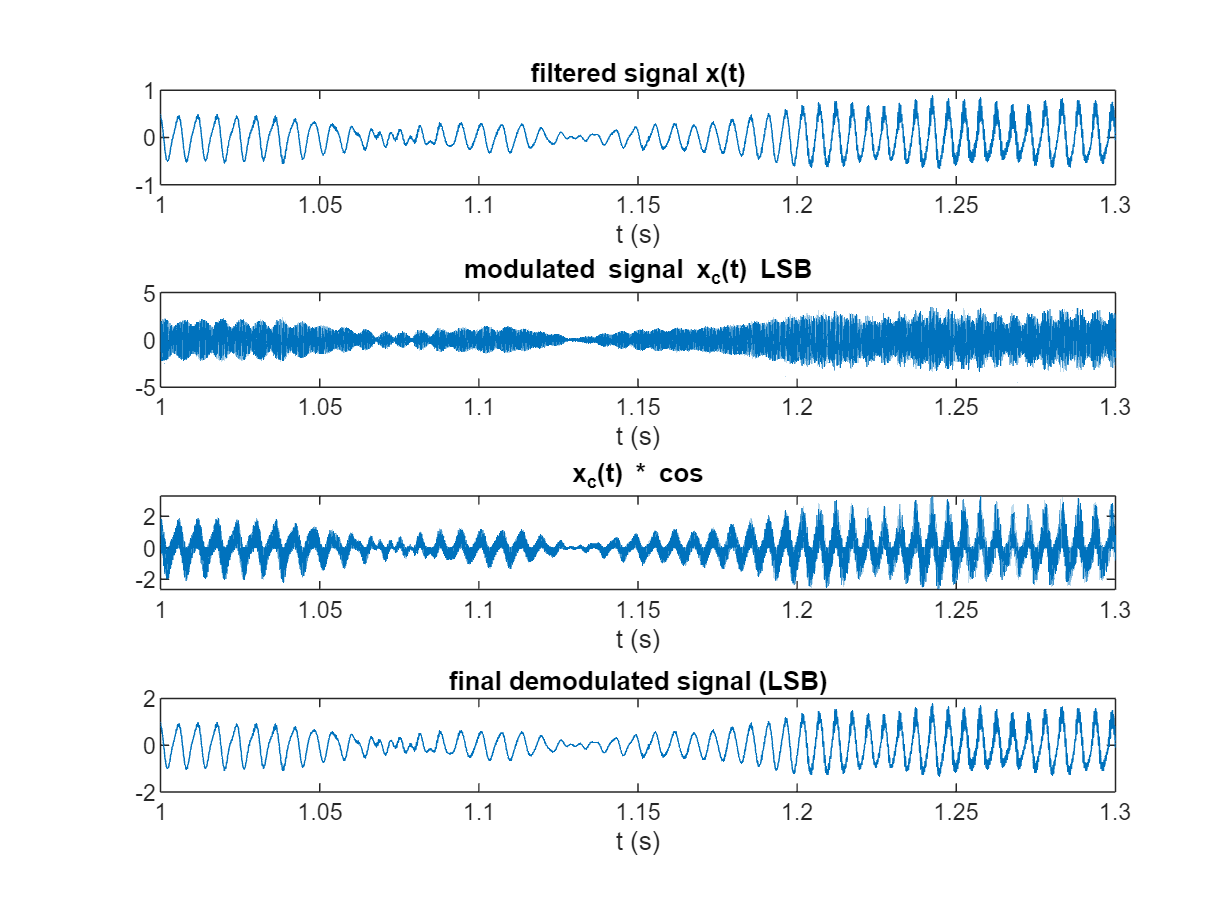

figure;
subplot(4,1,1);
plot (time_domain, x_in_filtered_5k);
xlabel('t (s)');
title('filtered signal x(t)');
xlim([1,1.3]);
subplot(4,1,2);
plot(time_domain, real(LSB_out));
xlabel('t (s)');
title('modulated signal x_c(t) LSB');
xlim([1,1.3]);
subplot(4,1,3);
plot(time_domain, real(x_dm_LSB));
xlabel('t (s)');
title('x_c(t) * cos');
xlim([1,1.3]);
subplot(4,1,4);
plot(time_domain, real(x_LSB_out));
xlabel('t (s)');
title('final demodulated signal (LSB)');
xlim([1,1.3]);

% sound(x_in, FS);
% sound(x_in_filtered_5k, FS);
% sound(real(x_USB_out), FS);
% sound(real(x_LSB_out), FS);

function X_tilda = Hilbert(pre_F,freq_vector)
    n = length(freq_vector);
    X_tilda=zeros(n,1);
    for i = (1:n)
        if(freq_vector(i) >= 0)
            X_tilda(i)= -1*pre_F(i)* 1j;
        else
            X_tilda(i)=pre_F(i)* 1j;
        end
    end
end
function New_F = LPfilter(pre_F,freq_vector, f)
    n = length(freq_vector);
    New_F=zeros(n,1);
    for i = (1:n)
        if(abs(freq_vector(i)) < f)
            New_F(i)=pre_F(i); 
        end
    end
end